clear all
close all
clc
gammagamma=[0.5 1 5 10];
risc=[1 2 6 20];
risc1=[0.5 3 10 40];



%load dati.mat
xx = -4:0.1:4;
line={'-','--','-.',':'}

line = 1×4 cell array
    {'-'}    {'--'}    {'-.'}    {':'}


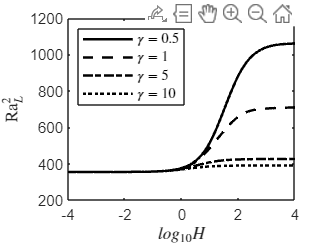


for i=1:length(gammagamma)
    if gammagamma(i)==0.5
        load Rc_logH_gamma=0.5.mat
        HH=10.^[-4 -3 -2 -1.5 -1 -0.5 0 0.5 1 2 3 3.5 4 ];
    end
    if gammagamma(i)==1
        load Rc_logH_gamma=1.mat
        HH=10.^[-4 -3 -2 -1.5 -1 -0.5 0 0.5 1 2 3 3.5 4 ];
    end
    if gammagamma(i)==5
        load Rc_logH_gamma=5.mat
        HH=10.^[-4 -3 -2 -1.5 -1 -0.5 0 0.5 1 2 3  4 ];
    end
    if gammagamma(i)==10
        load Rc_logH_gamma=10.mat
        HH=10.^[-4 -3 -2 -1.5 -1 -0.5 0 0.5 1 2 3  4 ];
    end
    yy = spline(log10(HH),Rc,xx);
    %subplot(2,2,i)
    plot(xx,yy,'k',LineStyle=line{i},LineWidth=1.5)
    xlabel('$log_{10} H$',Interpreter='latex')
ylabel('$\mathrm{Ra}_L^2$',Interpreter='latex')
LegendStrings= "$\gamma=$" + string(gammagamma);
legend(LegendStrings,Interpreter="latex",Location="northwest")
    %axis([-4 4 Rc(1)-10*risc1(i) Rc(end)+3*risc(i)])
    hold on
end